## Corr_len_cal

Find correlation length scale from measurement 

- use 1-D transects

- use 2-D plane

- compare length scales of both cases

clear
close all

ACO_lat= 22.738772;                  % June 2017
ACO_lon= -158.006186;                % June 2017

Load an inversion file: October 2018 (HEM)

cd /Users/testuser/Documents/ONR_RAP/Data/inversion_file
load('HEM_inverse_solution_Oct2018_originaldepth.mat')
tx_lat_HEM = tx_lat;
tx_lon_HEM = tx_lon;

Extract ttp measurements contributed from ocean features and plot tx map

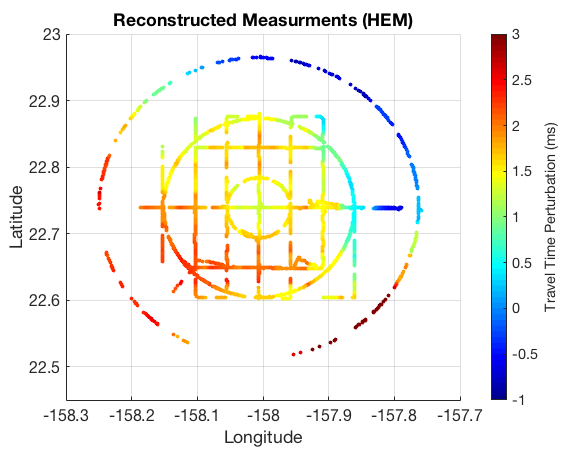

d_recov_ocean_HEM = G(:,1:end-3)*m_recov(1:end-3);

f1 = figure(1);
s1 = scatter(tx_lon_HEM,tx_lat_HEM);
color_range = [-1 3];
fpos = [0 0.2];
plot_RAP_txmap(f1,s1,'Reconstructed Measurments (HEM)',color_range,d_recov_ocean_HEM,fpos);

Load an inversion file: October 2018 (icListen)

cd /Users/testuser/Documents/ONR_RAP/Data/inversion_file
load('icListen_inverse_solution_Oct2018_originaldepth.mat')
tx_lat_ic = tx_lat;
tx_lon_ic = tx_lon;

Extract ttp measurements contributed from ocean features and plot tx map

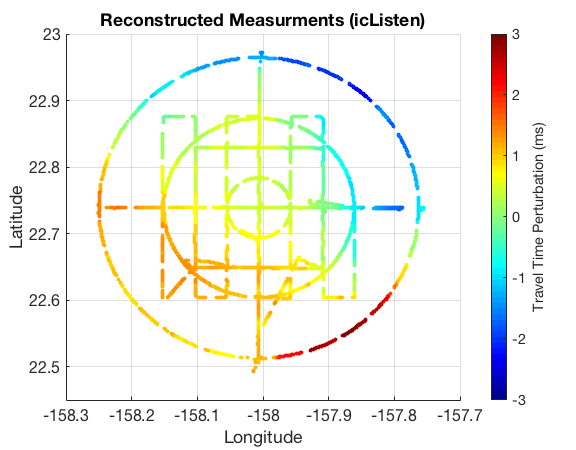

d_recov_ocean_ic = G(:,1:end-3)*m_recov(1:end-3);

f2 = figure(2);
s2 = scatter(tx_lon_ic,tx_lat_ic);
color_range = [-3 3];
fpos = [0.5 0.2];
plot_RAP_txmap(f2,s2,'Reconstructed Measurments (icListen)',color_range,d_recov_ocean_ic,fpos);

Set up radial transect Lat ~22.74

Lat = 22.73-22.75

Lon = -157.8 – -158.30

resample data

HEM

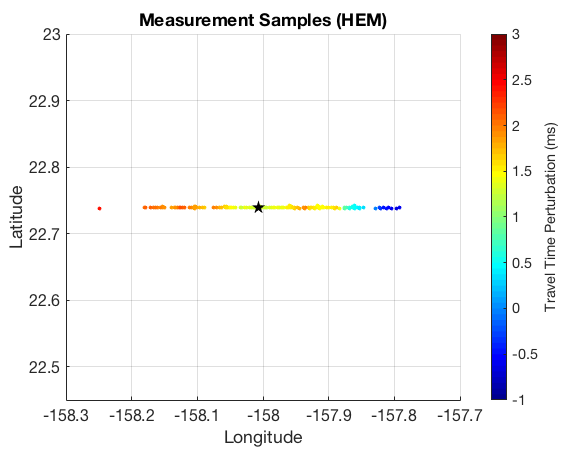

lonlim = find((tx_lon_HEM<-157.75 & tx_lon_HEM >-158.3)  == 1);
latlim = find((tx_lat_HEM< 22.742 & tx_lat_HEM > 22.737) == 1);
keep_ind = intersect(lonlim,latlim);
% resample
L = 5;
keep_ind = keep_ind(1:L:end);

d_HEM1 = d_recov_ocean_HEM(keep_ind);
tx_lon_HEM1 = tx_lon_HEM(keep_ind);
tx_lat_HEM1 = tx_lat_HEM(keep_ind);

f3 = figure(3);
s3 = scatter(tx_lon_HEM1,tx_lat_HEM1);
color_range = [-1 3];
fpos = [0.1 0.6];
plot_RAP_txmap(f3,s3,'Measurement Samples (HEM)',color_range,d_HEM1,fpos);
hold on
scatter(ACO_lon,ACO_lat,200,'pk','filled')

Create experimental variogram 

ttp = d_HEM1*1000;
sample = length(d_HEM1);
gamma = zeros(sample,sample);
x_range = zeros(sample,sample);
for ii = 1:sample
   for jj = ii:sample
       [x_range(ii,jj),~] = distance(tx_lat_HEM1(ii),tx_lon_HEM1(ii),tx_lat_HEM1(jj),tx_lon_HEM1(jj),referenceEllipsoid('WGS84'));
       gamma(ii,jj) = 0.5*(ttp(ii) - ttp(jj))^2;
   end
end
% raw variogram
gamma = reshape(gamma,1,sample*sample);
x_range = reshape(x_range,1,sample*sample);
gamma(find(gamma == 0)) = [];
x_range(find(x_range == 0)) = [];

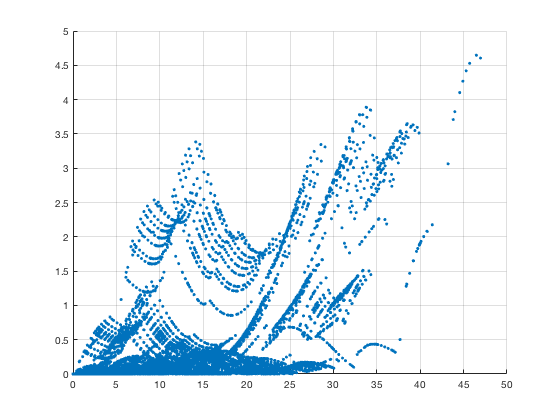


figure(4)
clf
scatter(x_range/1000,gamma,'.')
grid on

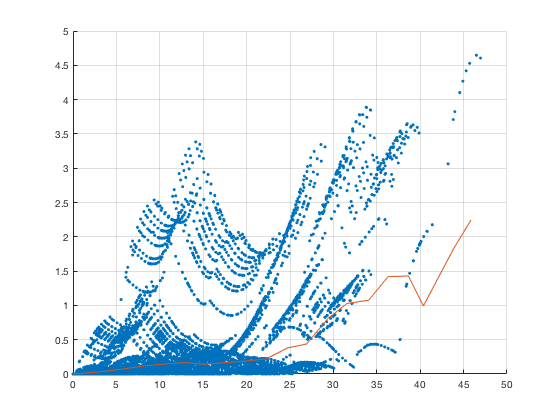

% experimental variogram
section_num = 20;
x_int = max(x_range)/section_num;
ex_gamma = zeros(1,section_num+1);
hk = zeros(1,section_num+1);
for ii = 2:section_num+1
    ind = find((x_range <= x_int*ii) & (x_range > x_int*(ii-1))); % indices of elements in the current interval
    Nk = length(ind);
    ex_gamma(ii) = sum(gamma(ind))/(2*Nk);
    hk(ii) = 1/Nk*sum(x_range(ind));
end
figure(4)
hold on
plot(hk/1000,ex_gamma)